##  E_E 521 Analysis of Power Systems

### Power Flow Project

### Sajjad Uddin Mahmud | WSU ID: 011789534

### Initializing MATLAB

close all;
clear all;
clc;

### Reading The IEEE Test System Data

In this project, we study IEEE 14 Bus test system.

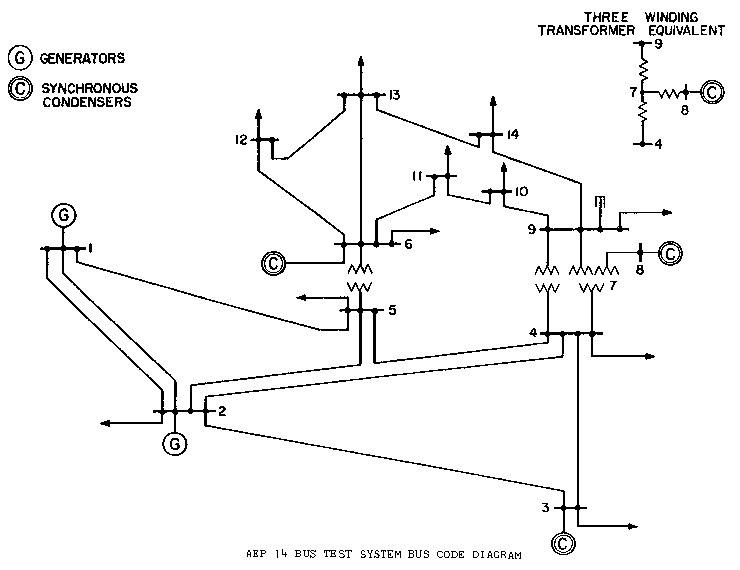

Fig. 01: IEEE 14 Bus Power System

At first, we read the data from the IEEE 14 Bus test system from a pre-formatted excel file which has been created from the [ieee14cdf.txt](http://labs.ece.uw.edu/pstca/pf14/pg_tca14bus.htm).

% Setting Up The Path
addpath('D:\One_Drive_Sajjad\OneDrive - Washington State University (email.wsu.edu)\Documents\Sajjad Uddin Mahmud\1. Courses\2. Fall 2022\EE 521 Analysis of Power System\Assignment\EE 521 Power Flow Project 01');

%--------------------------------------------------------------------------------------
%% Reading From Bus Data

% Bus Number
Bus_Number_Data = xlsread('IEEE14_Formatted.xlsx','A3:A16');
Total_Bus = max(Bus_Number_Data);

% Bus Type
Bus_Type_Data = xlsread('IEEE14_Formatted.xlsx','G3:G16');
PQ_Bus_Type = 0;
PV_Bus_Type = 2;
Slack_Bus_Type = 3;

% Bus Information
Base_MVA_Data = 100;
P_Load_Data = xlsread('IEEE14_Formatted.xlsx','J3:J16');
Q_Load_Data = xlsread('IEEE14_Formatted.xlsx','K3:K16');
P_Gen_Data = xlsread('IEEE14_Formatted.xlsx','L3:L16');
Q_Gen_Data = xlsread('IEEE14_Formatted.xlsx','M3:M16');

% Bus Shunt Conductance and Shunt Susceptance
G_Shunt_Bus_Data = xlsread('IEEE14_Formatted.xlsx','R3:R16');
B_Shunt_Bus_Data = xlsread('IEEE14_Formatted.xlsx','S3:S16');

%--------------------------------------------------------------------------------------
% Reading From Branch Data

% Branch Number
From_Bus_Data = xlsread('IEEE14_Formatted.xlsx','A19:A38');
To_Bus_Data = xlsread('IEEE14_Formatted.xlsx','B19:B38');

% Branch Resistance Per Unit
R_Branch_Data = xlsread('IEEE14_Formatted.xlsx','G19:G38');

% Branch Reactance Per Unit
X_Branch_Data = xlsread('IEEE14_Formatted.xlsx','H19:H38');

% Line Charging B Per Unit
B_Branch_Data = xlsread('IEEE14_Formatted.xlsx','I19:I38');

% Transformer Final Turns Ratio
XFR_TurnRatio_Data = xlsread('IEEE14_Formatted.xlsx','O19:O38');

### Creating Y Bus

At first we create a empty matrix for Y bus of a dimension based on the total bus number of the test system.

% Initializing Y Bus
Y_Bus = zeros(Total_Bus);

We calculate impedance and admittance of each branch.

Branch impedance between bus a and b: $$z_{ab} = r_{ab} + jx_{ab}$$ and branch admittance between bus a and b:  $$y_{ab}=\frac{1}{z_{ab}}$$

Z_Branch = zeros(length(From_Bus_Data),1);
Y_Branch = zeros(length(From_Bus_Data),1);

% Loop: Calculating Impedance and Admittance
for k = 1:length(From_Bus_Data)
    Z_Branch(k) = R_Branch_Data(k) + 1i*X_Branch_Data(k); % Per Unit Impedance
    Y_Branch(k) = 1/(Z_Branch(k)); % Per Unit Admittance
end

We also calculate the bus own shunt admittance.

% Calculating Bus Shunt Admittance
Y_Shunt_Bus = G_Shunt_Bus_Data + 1i.*B_Shunt_Bus_Data;

Next, we calculate the off-diagonal entries of the Y bus matrix.

Diagonal entries: $$Y_{aa}=\sum_{k=1}^N (y_{ak} + j \frac{B_{ak}}{2 })=\sum_{k=1}^N( \frac{1}{r_{ak}+jx_{ak}} + j \frac{B_{ak}}{2 })+jB_{a}$$

Off-Diagonal entries: $$Y_{ab}=Y_{ba}=- (\sum y_{ab})$$

% Loop: Calculating Diagonal and Off-Diagonal Entries of The Y Bus Matrix
for k = 1:length(Y_Branch)
    Y_Bus(From_Bus_Data(k),From_Bus_Data(k)) = Y_Bus(From_Bus_Data(k),From_Bus_Data(k)) + Y_Branch(k) + 1j*(B_Branch_Data(k)/2);
    Y_Bus(From_Bus_Data(k),To_Bus_Data(k)) = - Y_Branch(k);
    Y_Bus(To_Bus_Data(k),From_Bus_Data(k)) = Y_Bus(From_Bus_Data(k),To_Bus_Data(k));
end

% Loop: Adding Bus Shunt Admittance
for k = 1:length(Total_Bus)
    Y_Bus(k,k) = Y_Bus(k,k) + Y_Shunt_Bus(k); 
end

% Converting Y Bus Data into Polar Form
[Y_Bus_Theta, Y_Bus_Rho] = cart2pol(real(Y_Bus), imag(Y_Bus)); % The Theta are in radian

### Power Flow Equation